# B-spline curves

### Points for the approximation

P=[[2;-1],[0;0],[1;1],[2;0.5],[3;1],[4;0],[2;-1]]

P =     2.0000         0    1.0000    2.0000    3.0000    4.0000    2.0000
   -1.0000         0    1.0000    0.5000    1.0000         0   -1.0000


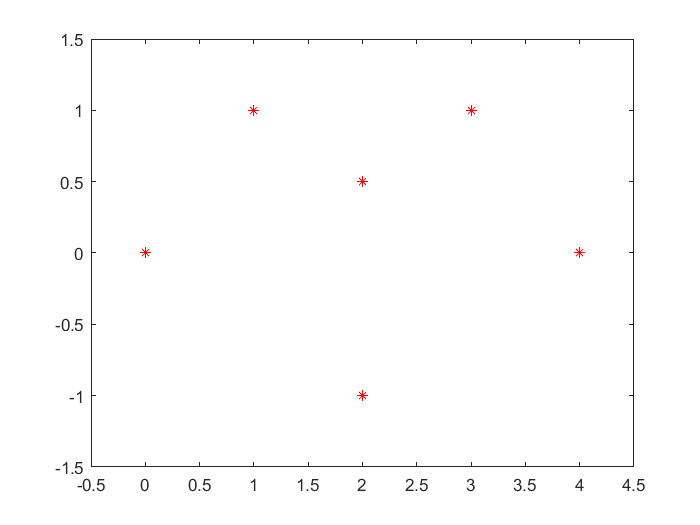

plot(P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5])

### Number of data

n=length(P)-1

n = 6

### Figure 1

p=5

p = 5

l=n+1-p

l = 2

T=[zeros(1,p) 0:l l*ones(1,p)]

T =      0     0     0     0     0     0     1     2     2     2     2     2     2


m=length(T)-1

m = 12

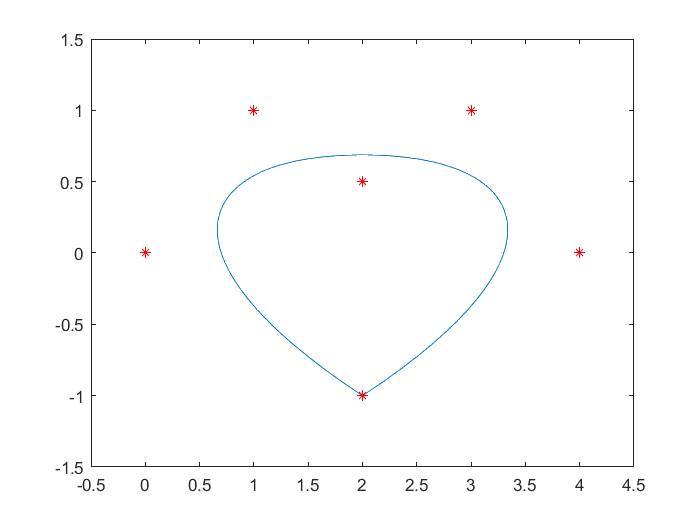

B=B_spline(T,p);
tt=linspace(0,l,101);
Bx=B_splval(B,P(1,:),tt);
By=B_splval(B,P(2,:),tt);
plot(Bx,By,P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5])

### Figure 2

p=1

p = 1

l=n+1-p

l = 6

T=[zeros(1,p) 0:l l*ones(1,p)]

T =      0     0     1     2     3     4     5     6     6


m=length(T)-1

m = 8

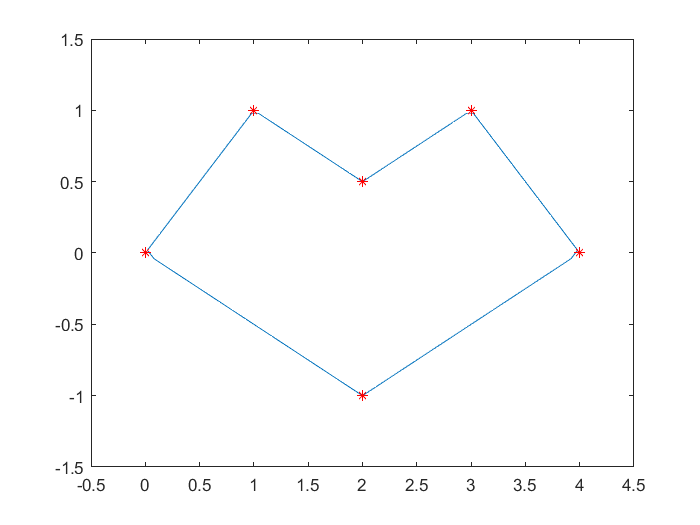

B=B_spline(T,p);
tt=linspace(0,l,101);
Bx=B_splval(B,P(1,:),tt);
By=B_splval(B,P(2,:),tt);
plot(Bx,By,P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5])

### Figure 3

p=3

p = 3

l=n+1-p

l = 4

T=[zeros(1,p) 0:l l*ones(1,p)]

T =      0     0     0     0     1     2     3     4     4     4     4


m=length(T)-1

m = 10

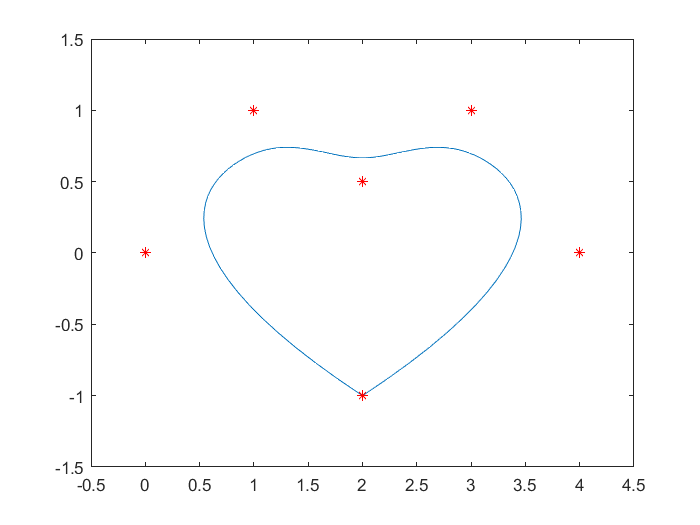

B=B_spline(T,p);
tt=linspace(0,l,101);
Bx=B_splval(B,P(1,:),tt);
By=B_splval(B,P(2,:),tt);
plot(Bx,By,P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5])

### Bézier curve

p=6

p = 6

l=n+1-p

l = 1

T=[zeros(1,p) 0:l l*ones(1,p)]

T =      0     0     0     0     0     0     0     1     1     1     1     1     1     1


m=length(T)-1

m = 13

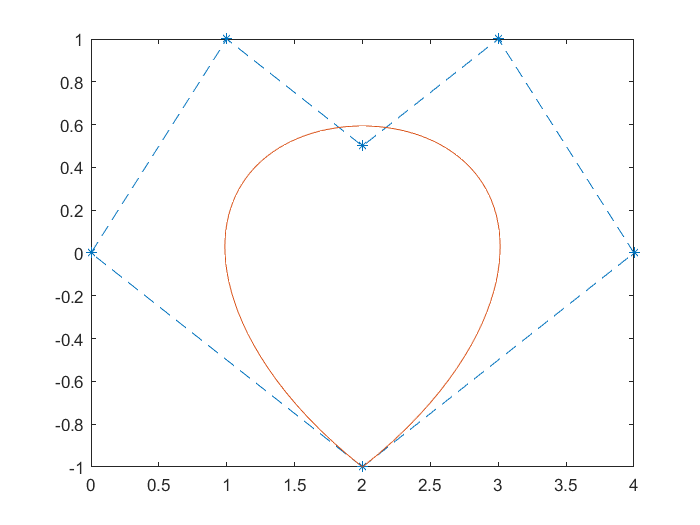

B=B_spline(T,p);
tt=linspace(0,l,101);
Bx=B_splval(B,P(1,:),tt);
By=B_splval(B,P(2,:),tt);
[Dx,Dy]=decastel(P(1,:),P(2,:),101);

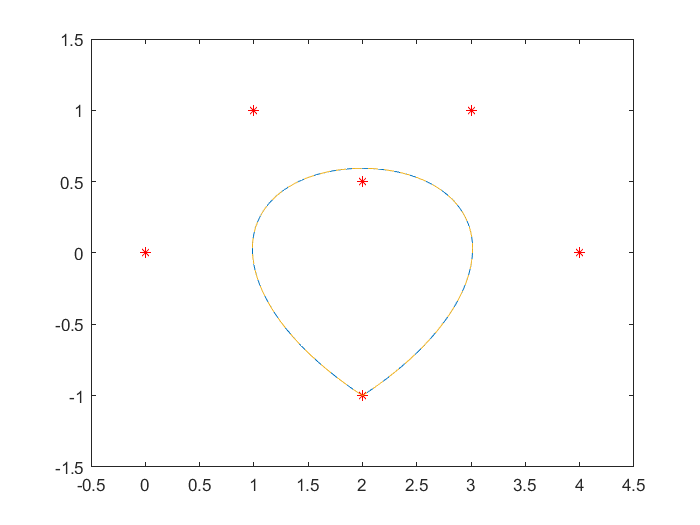

plot(Bx,By,P(1,:),P(2,:),'r*',Dx,Dy,'--')
axis([-0.5 4.5 -1.5 1.5])

### Heart

p=3

p = 3

l=n+1-p

l = 4

T=[0     0     0     0     2     2     2     4     4     4     4]

T =      0     0     0     0     2     2     2     4     4     4     4


m=length(T)-1

m = 10

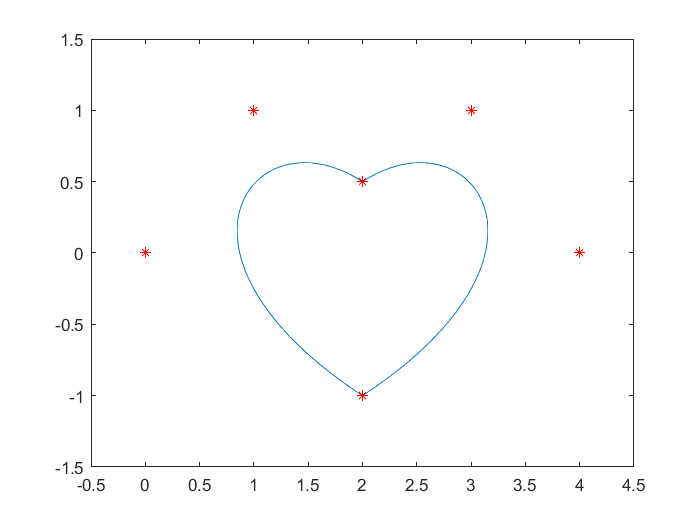

B=B_spline(T,p);
tt=linspace(0,l,101);
Bx=B_splval(B,P(1,:),tt);
By=B_splval(B,P(2,:),tt);
plot(Bx,By,P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5])